# Vision Sensor - Estimating Distance from robot base

Using empirically deried distance as a function of CenterY pixel from the VEX vision camera. 

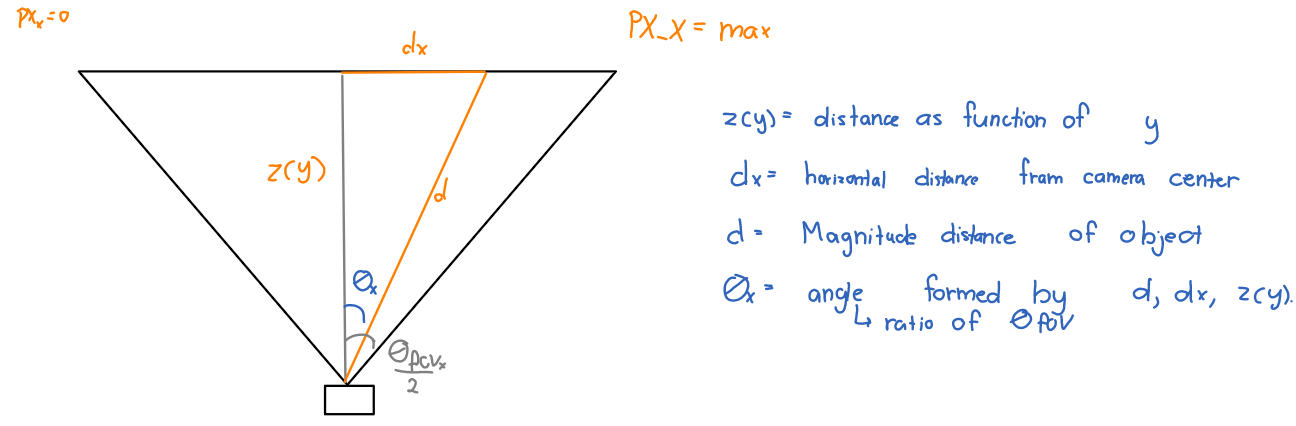

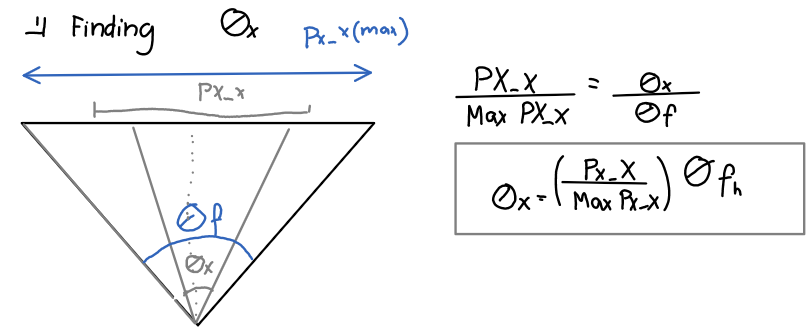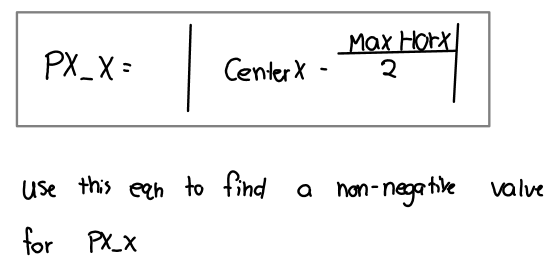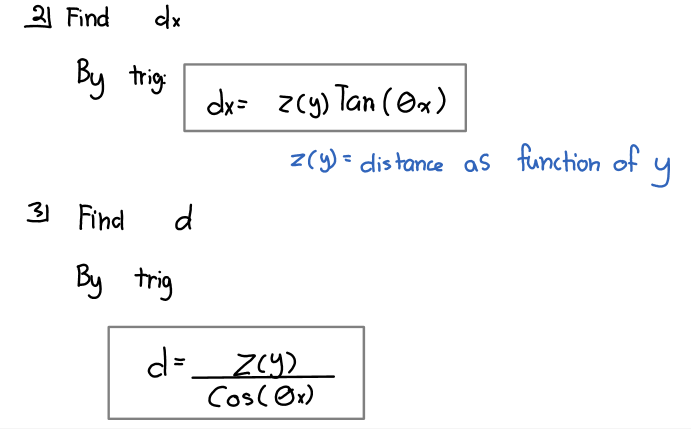

%clear storage and memory
clc;clear; close all;

%Define variables
syms MaxHorPx CenterX d_x d Z theta_x theta_fh NewCenterX

% solve for NewCenterX
NewCenterX = abs(CenterX - MaxHorPx/2)

$$NewCenterX = \left|\mathrm{CenterX}-\frac{\mathrm{MaxHorPx}}{2}\right|$$


% solve for theta x
theta_x = (NewCenterX/MaxHorPx) * theta_fh

$$theta\_x = \frac{\theta_{\mathrm{fh}}\,\left|\mathrm{CenterX}-\frac{\mathrm{MaxHorPx}}{2}\right|}{\mathrm{MaxHorPx}}$$


%solve for distance in X direction
d_x = Z * tand(theta_x)

$$d\_x = Z\,\tan\left(\frac{\pi \,\theta_{\mathrm{fh}}\,\left|\mathrm{CenterX}-\frac{\mathrm{MaxHorPx}}{2}\right|}{180\,\mathrm{MaxHorPx}}\right)$$


%solve for magnitude distance
d = Z * acosd(theta_x)

$$d = \frac{180\,Z\,\mathrm{acos}\left(\frac{\theta_{\mathrm{fh}}\,\left|\mathrm{CenterX}-\frac{\mathrm{MaxHorPx}}{2}\right|}{\mathrm{MaxHorPx}}\right)}{\pi }$$